# Using GPT-4 with Vision

This script demonstrates a chat interaction with the OpenAI Chat Completions API about images passed as part of the message. You must have access to GPT-4 Turbo with Vision, `gpt-4-vision-preview`, to run this example. 

% Use the valid API key from the paid OpenAI API account
loadenv(".env")
addpath('..') 

## Asking questions about an image using a URL

Load the sample image from Wikipedia.

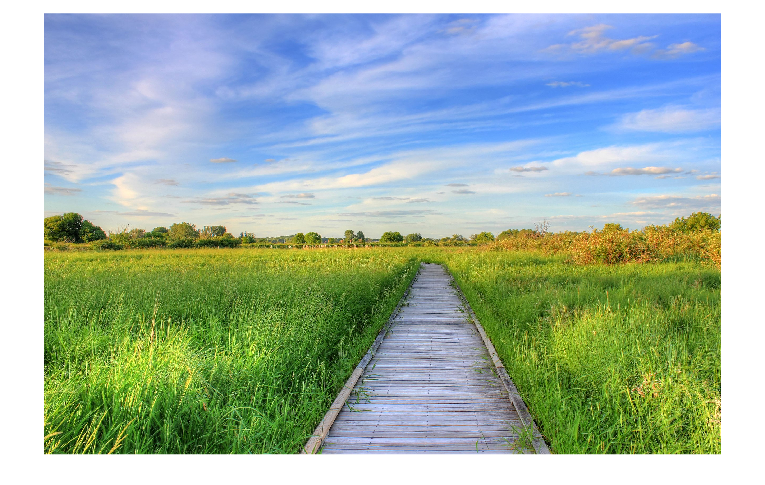

image_url = 'https://upload.wikimedia.org/wikipedia/commons/thumb/d/dd/Gfp-wisconsin-madison-the-nature-boardwalk.jpg/2560px-Gfp-wisconsin-madison-the-nature-boardwalk.jpg';
im = imread(image_url);
imshow(im)

Ask questions about the image with the URL. Select `gpt-4-vision-preview` model to create a chat object

chat = openAIChat("You are an AI assistant.", ModelName="gpt-4-vision-preview"); 

Create a message and pass the image url along with the prompt.

messages = openAIMessages;
messages = addUserMessageWithImages(messages,"What is in the image?",string(image_url));

Generate a response. 

[txt,~,response] = generate(chat,messages);
if response.StatusCode == "OK"
    disp(txt)
else
    response.Body.Data.error
end

The image shows a wooden boardwalk extending through a lush green wetland or grass


## Asking questions about an image from a file

Load a sample image from built-in datasets.

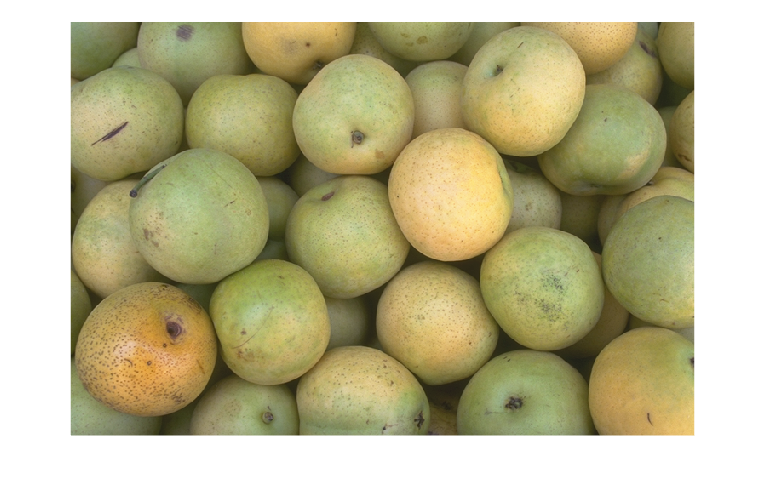

image_path = "pears.png";
im = imread(image_path);
imshow(im)

Ask questions about the image with the file path of the image. 

messages = openAIMessages;
messages = addUserMessageWithImages(messages,"What is in the image?",image_path);

Generate a response. 

[txt,message,response] = generate(chat,messages);
if response.StatusCode == "OK"
    disp(txt)
else
    response.Body.Data.error
end

The image displays a collection of yellowish-green fruits that appear to be pears


*Copyright 2024 The MathWorks, Inc.*